# Diseño controlador H-infinito / Sensibilidad Mixta

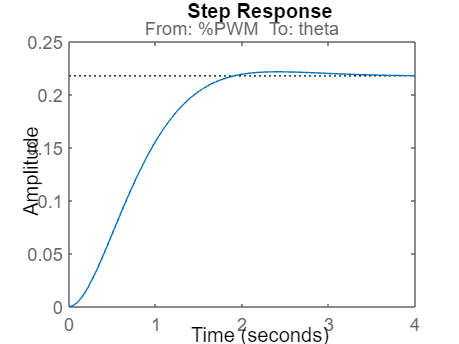

clear; clc; close all; 
addpath("../../../data/")
addpath("../../../controllers/Hinf/")
load("TF.mat")
ang_Lin = 85;
[Gss, G] = getNewTF(ang_Lin);
step(Gss); %% Lazo abierto de planta

Definición de las prestaciones: 

- Seguimiento de Referencia Perfecto (ep = 0) 

- Accion de Control entre (0 < u < 100) [ % PWM ]

- Menor tiempo posible (Mayor ancho de banda) 

- Rechazo a perturbaciones 

Definición de señales 

- ***El controlador recibe error en radianes y lo convierte a Porcentaje de PWM % ***

## Definición de Filtros de Ponderación

- $S$ -> Sensibilidad del sistema 

- KS -> Accion de control 

- T -> Sensibilidad Complementaria 


$$T+S=1$$
 

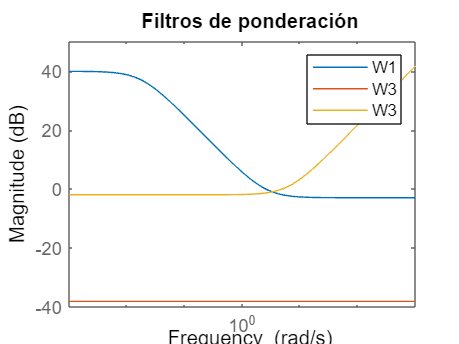

% Definición de filtros 

s = tf('s'); 
%W1 = makeweight(80, 0.4, 1e-6) * 1/(s/0.1 + 1);       %% Sensibilidad 
W2 = ss(1/50 * deg2rad(35));      %% Acción de Control  
%W3 = makeweight(1e-6,1.3, 200);      %% Sensibilidad Complementaria



freqC1=5;freqC2=32;freqC3=5;

% Selección de filtros 
W1 = makeweight(db2mag(40),[freqC1 db2mag(-2)],db2mag(-3)); % S 
%W2  =makeweight(db2mag(-35),[freqC2 db2mag(-32.5)],db2mag(-10)); % KS 
%W2 = db2mag(35*pi/180*30);
W3 = makeweight(db2mag(-2),[freqC3 db2mag(0)],db2mag(100)); % T


% Grafica de filtros 
bodemag(W1, W2, W3);
legend("W1", "W3", "W3"); 
title("Filtros de ponderación"); 


[K, CL, GAM] = mixsyn(Gss, W1, W2, W3); % Solucion problema H-infinito
GAM

GAM = 0.9895

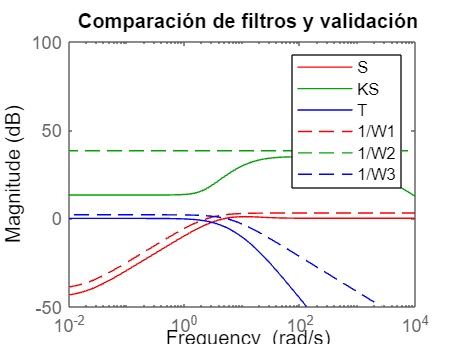


% Validación de filtros y H infinito 
S = feedback(1, K * G);
KS = K * S; 
T = 1 - S; 

% Graficas 
bodemag(S, "r-", KS, "g-", T, "b-"); hold on; 
bodemag(1/W1, "r--", 1/W2, "g--", 1/W3, 'b--'); hold off;
title("Comparación de filtros y validación"); 
legend("S", "KS", "T", "1/W1", "1/W2", "1/W3")
axis([1e-2 10e3, -50, 100]); 

## Respuesta de lazo cerrado

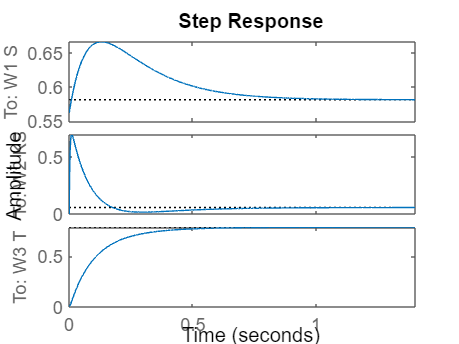

% MAtriz de transferencia aumentada
CL.OutputName = {'W1 S', 'W2 KS', 'W3 T'}; 
step(CL); 

OL = series(K, G); 
T = feedback(OL, 1); 
U = feedback(K, G); 


%% Respuesta directa 
step(T); 
BW = bandwidth(T)

BW = 4.6617

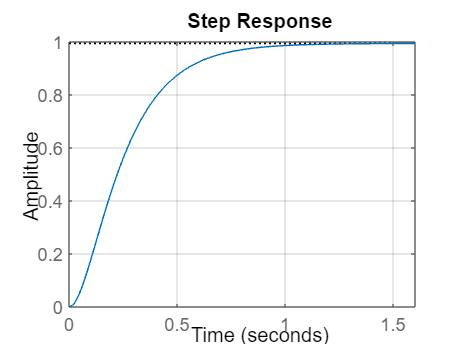

grid on; 

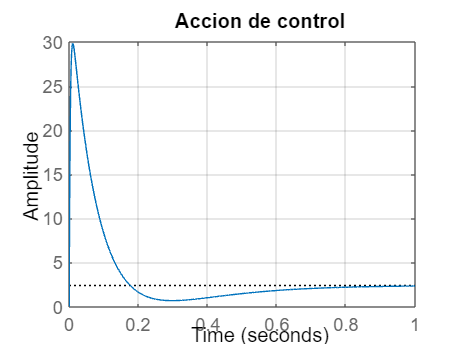


% Respuesta de accion de control
step(pi/6 * U);  
title("Accion de control"); grid on; 

% Función de transferencia; 
size(K); 

State-space model with 1 outputs, 1 inputs, and 4 states.


Ktf = tf(K); 

## Implementacion en arduino

Ts = 2.5e-3;  % Tiempo de muestreo

HinfDiscrete = c2d(K, Ts, 'tustin')

HinfDiscrete =
 
  A = 
              x1         x2         x3         x4
   x1     0.9999  8.675e-23  6.763e-17  3.874e-18
   x2   0.005608    -0.9998     0.5065  0.0004489
   x3    0.02201  3.945e-08      0.988   0.001762
   x4      17.61  3.156e-05     -9.576     0.4095
 
  B = 
              u1
   x1      0.005
   x2  1.402e-05
   x3  5.503e-05
   x4    0.04402
 
  C = 
            x1       x2       x3       x4
   y1     7258  0.01301    -3942     -240
 
  D = 
          u1
   y1  18.15
 
Sample time: 0.0025 seconds
Discrete-time state-space model.



%save("controllers/Hinf/Hinf.mat", "HinfDiscrete"); 
save("Hinf.mat", "HinfDiscrete"); 

## Revision en discreto

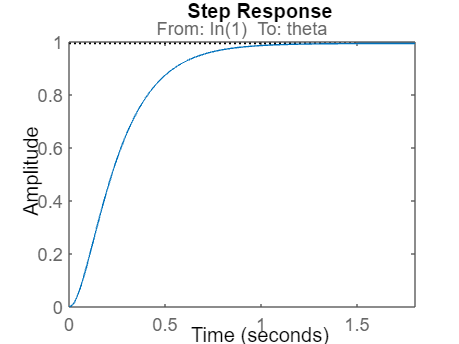

Gdiscrete = c2d(Gss, Ts, 'tustin'); 

Tdiscrete = feedback(series(HinfDiscrete, Gdiscrete), 1); 
step(Tdiscrete)

## Simulación Sistema No Lineal

DirectCMD = 52;
t1 = 70;
t2= 90;
%results = sim("controllers/Hinf/design/hinfNL.slx",100); 
results = sim("hinfNL.slx",100); 

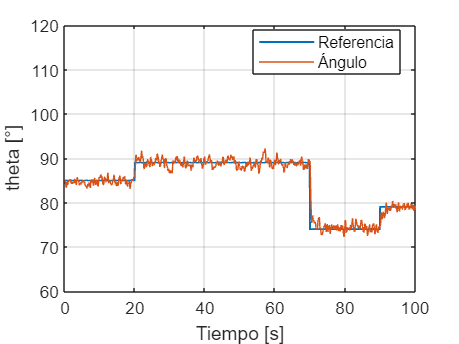

t = results.tout; % tiempo de simulación    

% Estados del sistema
theta = results.theta.Data;
ref = results.Ref.Data;

figure()
plot(t,ref,'-', 'LineWidth',1); 
hold on; 
plot(t,theta);
hold off
grid on;
xlabel('Tiempo [s]');
ylabel('theta [°]');
ylim([60 120])
legend('Referencia', 'Ángulo','Location','best');